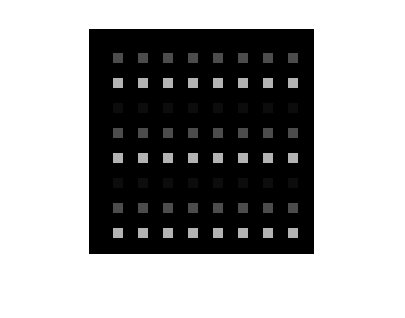

img = imread("shapes_2.png");
count = [0 0 0];


[H,S,V] = rgb2hsv(img);
figure; 
%
imshow(H);

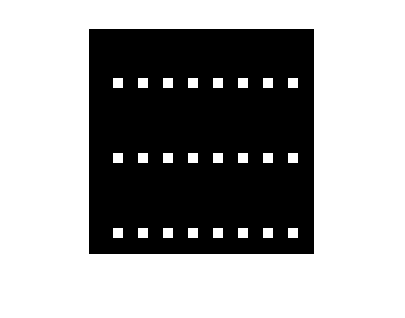



blue = H > 0.6;
green = H > 0.25 & H < 0.6;
red = H < 0.1 & H > 0;
%
imshow(blue);

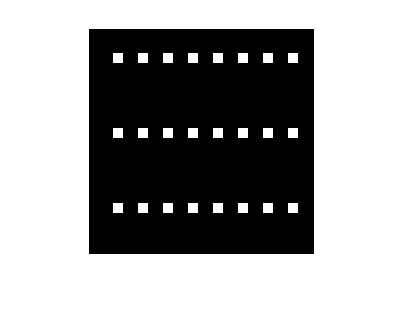

imshow(green);

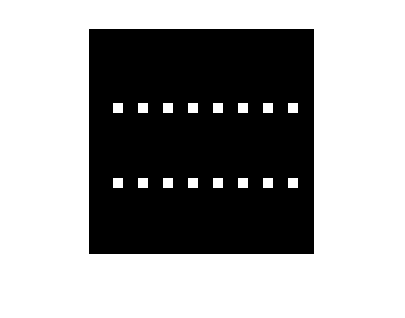

imshow(red);


stats = regionprops("table", blue);
count(1) = length(stats.Centroid);
stats = regionprops("table", green);
count(2) = length(stats.Centroid);
stats = regionprops("table", red);
count(3) = length(stats.Centroid);

